cfg = struct with fields:
    headmodel: [1×1 struct]
         grad: [1×1 struct]
      fsample: 256


cfg = struct with fields:
    headmodel: [1×1 struct]
         grad: [1×1 struct]
      fsample: 256
          dip: [1×1 struct]
     relnoise: 5
       trllen: 40


using gradiometers specified in the configuration
NUMTRL = 1
11 NUMTRL = 1
computing data data
computing data data for trial 1

RMS value of data data is 1.79335e-09
the call to "ft_dipolesimulation" took 8 seconds and required the additional allocation of an estimated 0 MB


the input is raw data with 51 channels and 1 trials


 In fixsampleinfo at line 88
 In ft_datatype_raw at line 149
 In ft_checkdata at line 267
 In ft_timelockanalysis at line 101



 In fixsampleinfo at line 101
 In ft_datatype_raw at line 149
 In ft_checkdata at line 267
 In ft_timelockanalysis at line 101

> In fixsampleinfo (line 102)
  In 

the input is timelock data with 51 channels and 256 timebins
the call to "ft_selectdata" took 1 seconds and required the additional allocation of an estimated 2 MB
Your data and configuration allow for multiple sensor definitions.


creating sourcemodel based on automatic 3D grid with specified resolution
using gradiometers specified in the configuration
creating 3D grid with 2 cm resolution
initial 3D grid dimensions are [12 12 12]
552 dipoles inside, 1176 dipoles outside brain
making tight grid
552 dipoles inside, 448 dipoles outside brain
the call to "ft_prepare_sourcemodel" took 2 seconds and required the additional allocation of an estimated 3 MB
scanning repetition 1
scanning grid
scanning grid 552/552

the call to "ft_sourceanalysis" took 12 seconds and required the additional allocation of an estimated 15 MB


the call to "ft_sourcedescriptives" took 0 seconds and required the additional allocation of an estimated 0 MB


the input is source data with 1000 brainordinates on a [10 10 10] grid
the call to "ft_selectdata" took 0 seconds and required the additional allocation of an estimated 1 MB
not plotting anatomy
not using an atlas
not using a region-of-interest


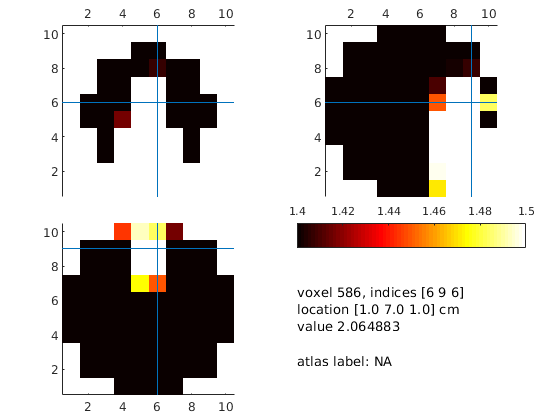


click left mouse button to reposition the cursor
click and hold right mouse button to update the position while moving the mouse
use the arrowkeys to navigate in the current axis
the call to "ft_sourceplot" took 4 seconds and required the additional allocation of an estimated 82 MB


ans = logical
   1


% create an array with some magnetometers at 12cm distance from the origin

[X, Y, Z] = sphere(10);
pos = unique([X(:) Y(:) Z(:)], 'rows');
pos = pos(pos(:,3)>=0,:);
grad = [];
grad.coilpos = 12*pos;
grad.coilori = pos; % in the outward direction
% grad.tra = eye(length(pos)); % each coils contributes exactly to one channel
for i=1:length(pos)
  grad.label{i} = sprintf('chan%03d', i);
end

% create a spherical volume conductor with 10cm radius
vol.r = 10;
vol.o = [0 0 0];

% note that beamformer scanning will be done with a 1cm grid, so you should
% not put the dipole on a position that will not be covered by a grid
% location later
cfg = [];
cfg.headmodel = vol;
cfg.grad = grad;
cfg.fsample = 256
cfg.dip.pos = [0 6 0];    % you can vary the location, here the dipole is along the z-axis
cfg.dip.mom = [0 1 10]';   % the dipole points along the x-axis
cfg.relnoise = 5;  % if noise is high, NAI shows nothing
cfg.trllen = 40
cfg.numtrl = 1;  % with few trials I get something strange for some reason
data = ft_dipolesimulation(cfg);

% compute the data covariance matrix, which will capture the activity of
% the simulated dipole
cfg = [];
cfg.covariance = 'yes';
timelock = ft_timelockanalysis(cfg, data);


% do the beamformer source reconstuction on a 1 cm grid
cfg = [];

fname_bads_mat = 'S01_off_move_MEGch_bads_upd.mat'

Undefined function or variable 'data_dir'.

cfg.headmodel = vol;
cfg.grad = grad;
cfg.resolution = 2;
cfg.method = 'lcmv';
cfg.lcmv.projectnoise = 'yes'; % needed for neural activity index
source = ft_sourceanalysis(cfg, timelock);

% compute the neural activity index, i.e. projected power divided by
% projected noise
cfg = [];
cfg.powmethod = 'none'; % keep the power as estimated from the data covariance, i.e. the induced power
source_nai = ft_sourcedescriptives(cfg, source);

cfg = [];
cfg.method = 'ortho';
cfg.funparameter = 'nai';
cfg.funcolorlim = [1.4 1.5];  % the voxel in the center of the volume conductor messes up the autoscaling
ft_sourceplot(cfg, source_nai);

cfg = [];
cfg.method = 'cloud';
cfg.funparameter = 'nai';
%cfg.funcolorlim = [1 2.3];  % the voxel in the center of the volume conductor messes up the autoscaling
cfg.cloudtype = 'point';
cfg.radius = 20
ft_sourceplot(cfg, source_nai); colorbar;
view(90,45)

cfg = [];
cfg.method = 'vertex';
cfg.funparameter = 'nai';
%cfg.funparameter = 'avg.pow';
%cfg.funcolorlim = [1.4 1.5];  % the voxel in the center of the volume conductor messes up the autoscaling
ft_sourceplot(cfg, source_nai); 
view(90,0)